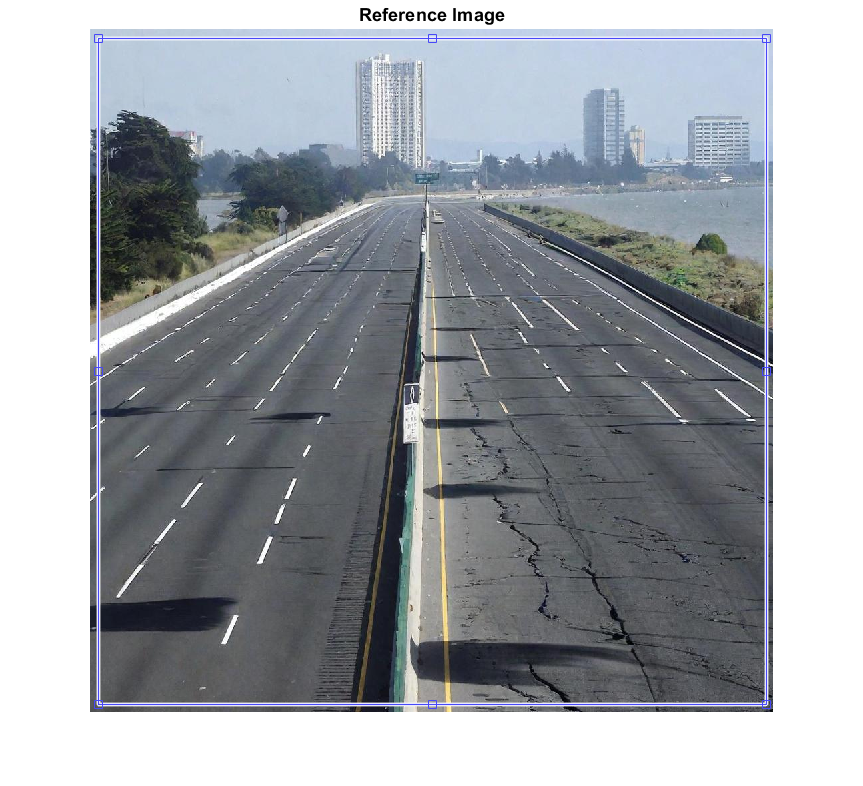

clc;
close all;
clear all;

% Load the reference image
RGB1 = imread('No_Traffic_Empty.jpeg');
figure; imshow(RGB1); title('Reference Image');

% Allow the user to draw a rectangle on the reference image
h = imrect;
wait(h);

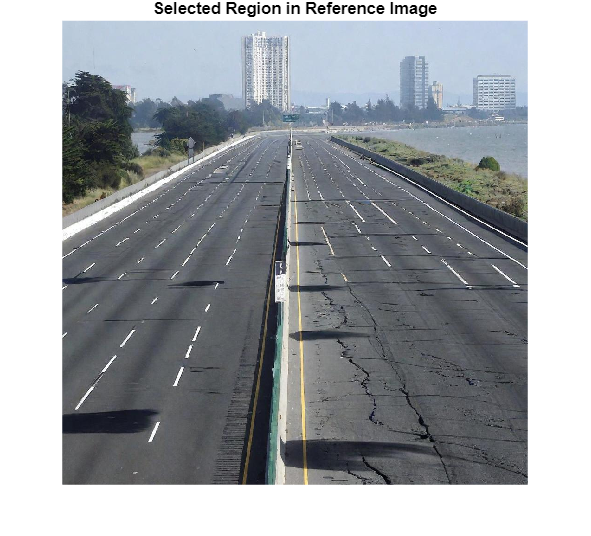

rect_position = round(getPosition(h));

% Extract the selected region from the reference image
selected_region_ref = imcrop(RGB1, rect_position);
figure; imshow(selected_region_ref); title('Selected Region in Reference Image');

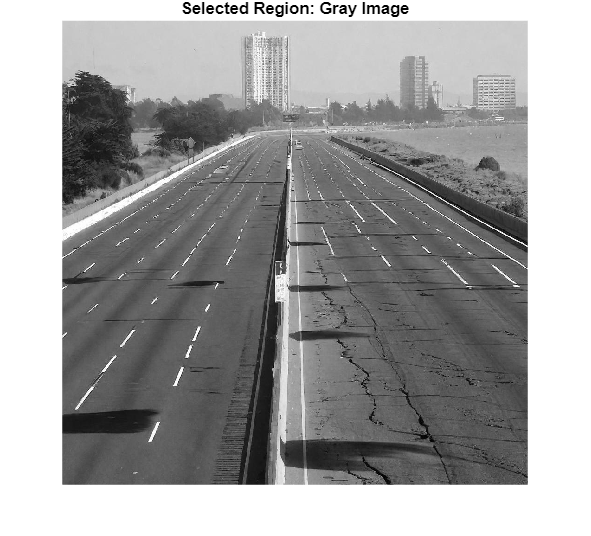


% Convert the selected region to grayscale
I1 = rgb2gray(selected_region_ref);
ID1 = im2double(I1);
figure; imshow(ID1); title('Selected Region: Gray Image');

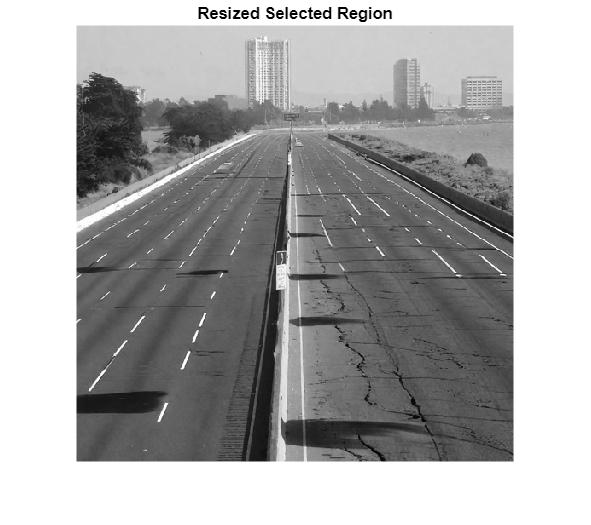


% Resize the selected region
IR1 = imresize(ID1, [512 512]);
figure; imshow(IR1); title('Resized Selected Region');

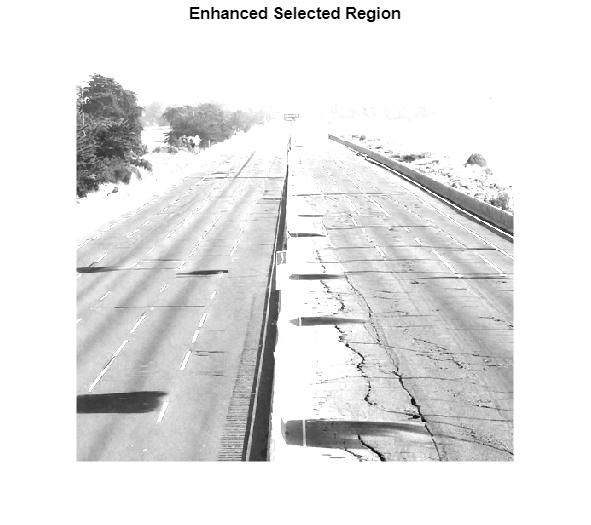


% Image Enhancement Power Law Transformation
c = 2;
g = 0.9;
for p = 1 : 512
    for q = 1 : 512
        IG1(p, q) = c * IR1(p, q).^g;  
    end
end
figure; imshow(IG1); title('Enhanced Selected Region');

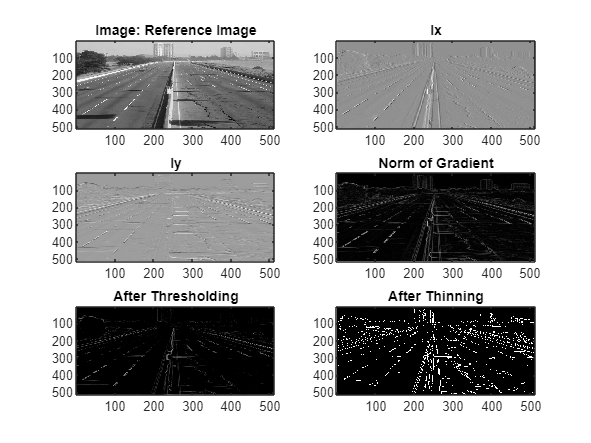


% Edge Detection
% The algorithm parameters:
% 1. Parameters of edge detecting filters:
%    X-axis direction filter:
Nx1 = 10; Sigmax1 = 1; Nx2 = 10; Sigmax2 = 1; Theta1 = pi/2;
%    Y-axis direction filter:
Ny1 = 10; Sigmay1 = 1; Ny2 = 10; Sigmay2 = 1; Theta2 = 0;
% 2. The thresholding parameter alfa:
alfa = 0.1;

% Get the initial Reference Image
figure; 
subplot(3,2,1)
IG1 = real(IG1);
imagesc(IG1);
title('Image: Reference Image');
colormap(gray);

% X-axis direction edge detection
subplot(3,2,2);
filterx = d2dgauss(Nx1, Sigmax1, Nx2, Sigmax2, Theta1);
Ix = conv2(IG1, filterx, 'same');
imagesc(real(Ix));
title('Ix');
% Y-axis direction edge detection
subplot(3,2,3)
filtery = d2dgauss(Ny1, Sigmay1, Ny2, Sigmay2, Theta2);
Iy = conv2(IG1, filtery, 'same');
imagesc(real(Iy));
title('Iy');
% Norm of the gradient (Combining the X and Y directional derivatives)
subplot(3,2,4);
NVI1 = sqrt(max(0, Ix.^2 + Iy.^2));
imagesc(real(NVI1));
title('Norm of Gradient');
% Thresholding
I_max = max(max(NVI1));
I_min = min(min(NVI1));
level = alfa * (I_max - I_min) + I_min;
subplot(3,2,5);
Ibw = max(NVI1, level .* ones(size(NVI1)));
imagesc(real(Ibw));
title('After Thresholding');
% Thinning (Using interpolation to find the pixels where the norms of
% gradient are local maximum.)
subplot(3,2,6);
[n, m] = size(Ibw);
for i = 2:n-1
    for j = 2:m-1
        if Ibw(i, j) > level
            X = [-1, 0, +1; -1, 0, +1; -1, 0, +1];
            Y = [-1, -1, -1; 0, 0, 0; +1, +1, +1];
            Z = [Ibw(i-1,j-1), Ibw(i-1,j), Ibw(i-1,j+1);
                 Ibw(i,j-1), Ibw(i,j), Ibw(i,j+1);
                 Ibw(i+1,j-1), Ibw(i+1,j), Ibw(i+1,j+1)];
            XI = [Ix(i,j)/NVI1(i,j), -Ix(i,j)/NVI1(i,j)];
            YI = [Iy(i,j)/NVI1(i,j), -Iy(i,j)/NVI1(i,j)];
            ZI = interp2(X, Y, Z, XI, YI);
            if Ibw(i,j) >= ZI(1) && Ibw(i,j) >= ZI(2)
                I_temp(i,j) = I_max;
            else
                I_temp(i,j) = I_min;
            end
        else
            I_temp(i,j) = I_min;
        end
    end
end
imagesc(real(I_temp));
title('After Thinning');
colormap(gray);

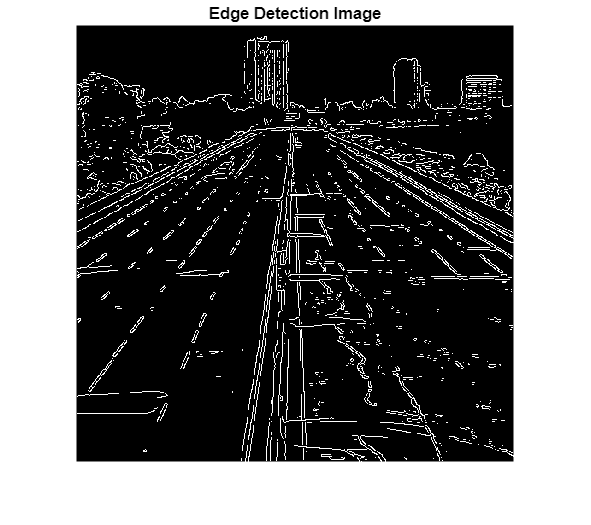

I_temp1 = I_temp;
figure; imshow(real(I_temp)); title('Edge Detection Image');

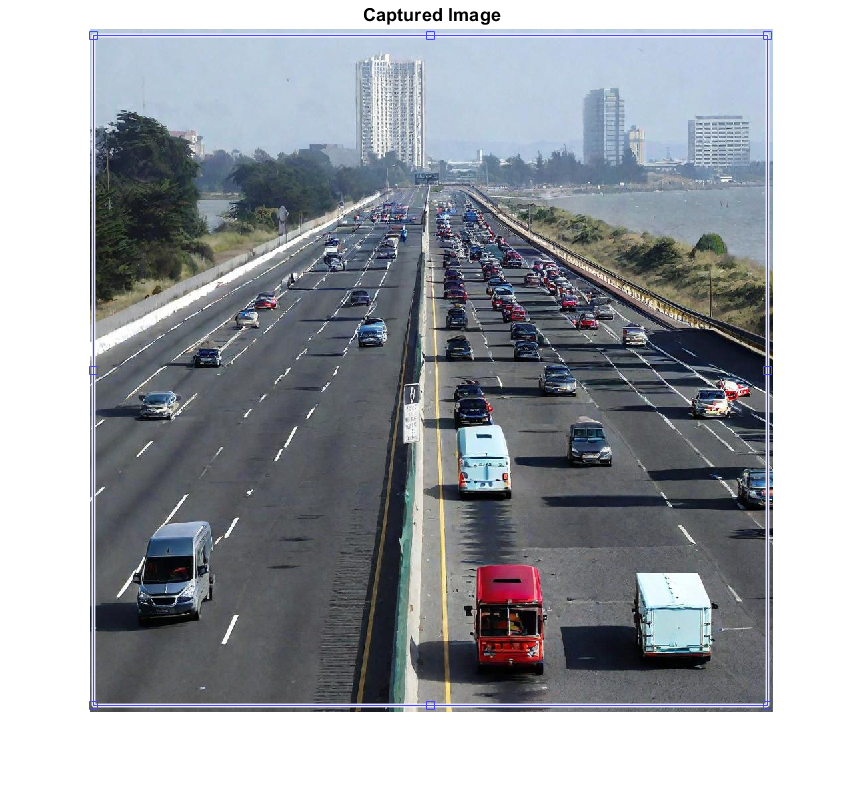


%%%%%%%%%%Captured Image%%%%%%%%%%
RGB2 = imread('Medium_Traffic_Empty.jpeg');
figure; imshow(RGB2); title('Captured Image');

% Allow the user to draw a rectangle on the captured image
h = imrect;
wait(h);

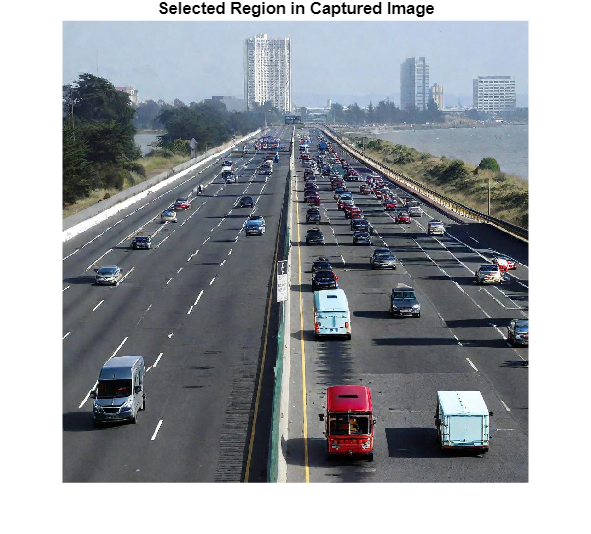

rect_position = round(getPosition(h));

% Extract the selected region from the captured image
selected_region_captured = imcrop(RGB2, rect_position);
figure; imshow(selected_region_captured); title('Selected Region in Captured Image');

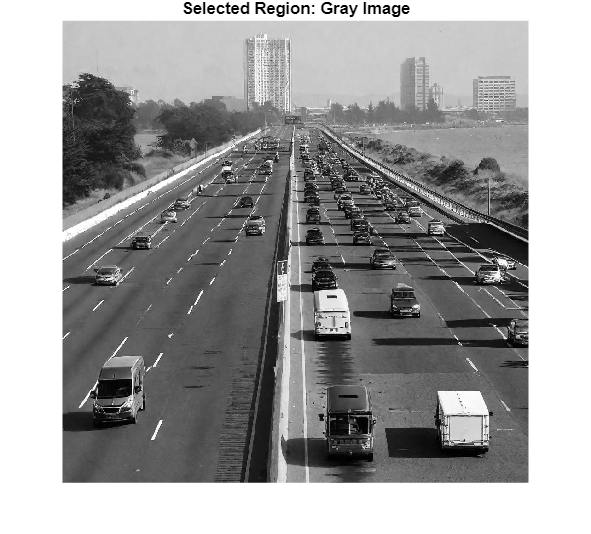


% Convert the selected region to grayscale
I2 = rgb2gray(selected_region_captured);
ID2 = im2double(I2);
figure; imshow(ID2); title('Selected Region: Gray Image');

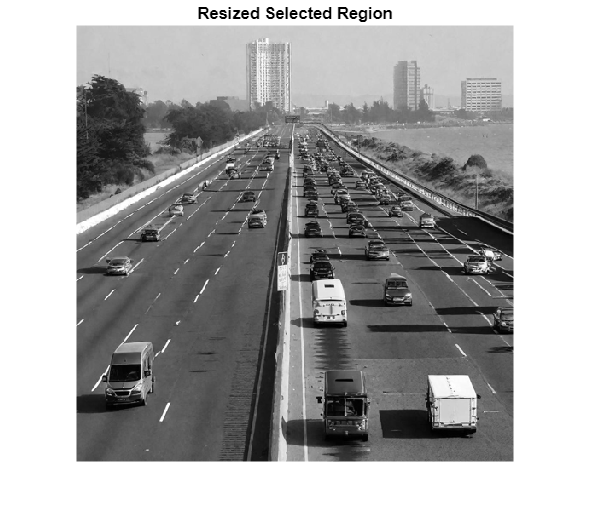


% Resize the selected region
IR2 = imresize(ID2, [512 512]);
figure; imshow(IR2); title('Resized Selected Region');

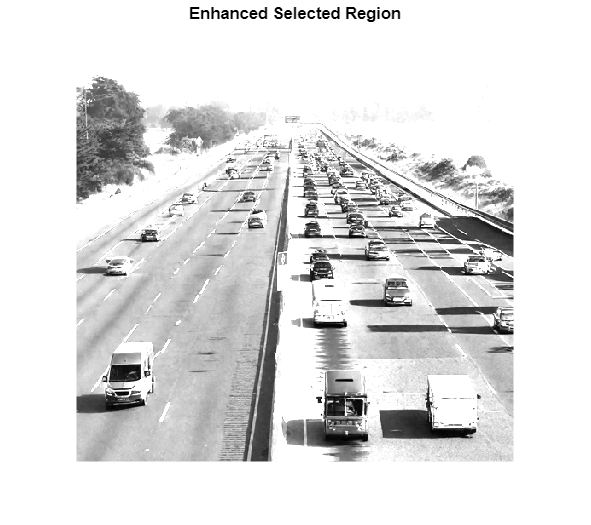


% Image Enhancement Power Law Transformation: Captured Image
for p = 1 : 512
    for q = 1 : 512
        IG2(p, q) = abs(c * IR2(p, q).^ g);
    end
end
figure; imshow(IG2); title('Enhanced Selected Region');

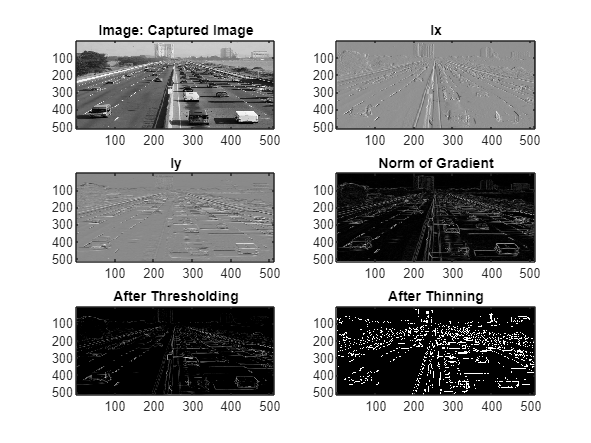


% Edge Detection
% The algorithm parameters (Same as for the reference image)

% Get the initial Captured Image
figure;
subplot(3,2,1);
imagesc(IG2);
title('Image: Captured Image');
% X-axis direction edge detection
subplot(3,2,2);
Ix = conv2(IG2, filterx, 'same');
imagesc(Ix);
title('Ix');
% Y-axis direction edge detection
subplot(3,2,3)
Iy = conv2(IG2, filtery, 'same');
imagesc(Iy);
title('Iy');
% Norm of the gradient (Combining the X and Y directional derivatives)
subplot(3,2,4);
NVI2 = sqrt(max(0, Ix.^2 + Iy.^2));
imagesc(NVI2);
title('Norm of Gradient');
% Thresholding
I_max = max(max(NVI2));
I_min = min(min(NVI2));
level = alfa * (I_max - I_min) + I_min;
subplot(3,2,5);
Ibw = max(NVI2, level .* ones(size(NVI2)));
imagesc(Ibw);
title('After Thresholding');
% Thinning (Using interpolation to find the pixels where the norms of
% gradient are local maximum.)
subplot(3,2,6);
[n, m] = size(Ibw);
for i = 2:n-1
    for j = 2:m-1
        if Ibw(i, j) > level
            X = [-1, 0, +1; -1, 0, +1; -1, 0, +1];
            Y = [-1, -1, -1; 0, 0, 0; +1, +1, +1];
            Z = [Ibw(i-1,j-1), Ibw(i-1,j), Ibw(i-1,j+1);
                 Ibw(i,j-1), Ibw(i,j), Ibw(i,j+1);
                 Ibw(i+1,j-1), Ibw(i+1,j), Ibw(i+1,j+1)];
            XI = [Ix(i,j)/NVI2(i,j), -Ix(i,j)/NVI2(i,j)];
            YI = [Iy(i,j)/NVI2(i,j), -Iy(i,j)/NVI2(i,j)];
            ZI = interp2(X, Y, Z, XI, YI);
            if Ibw(i,j) >= ZI(1) && Ibw(i,j) >= ZI(2)
                I_temp(i,j) = I_max;
            else
                I_temp(i,j) = I_min;
            end
        else
            I_temp(i,j) = I_min;
        end
    end
end
imagesc(I_temp);
title('After Thinning');
colormap(gray);

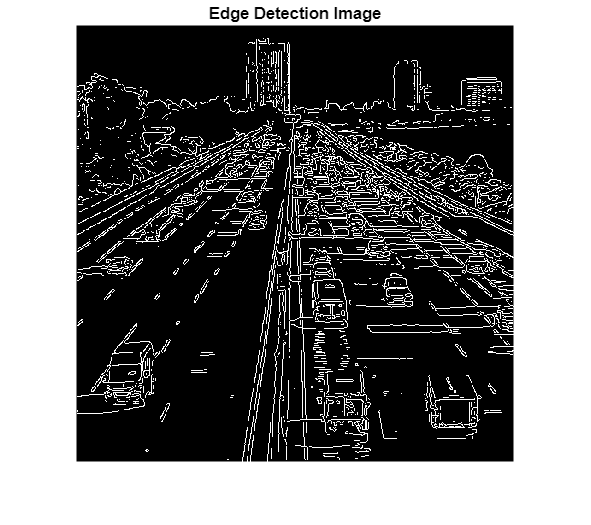

I_temp2 = I_temp;
figure; imshow(real(I_temp)); title('Edge Detection Image');


%%%%%%%%%%Image Matching%%%%%%%%%%
% Use Normalized Cross-Correlation (NCC) for template matching
corr_result = normxcorr2(IG2, IG1);

% Extract the relevant portion of the correlation result
[~, idx] = max(corr_result(:));
[y, x] = ind2sub(size(corr_result), idx);

% Calculate the matching score
match_score = max(corr_result(:));

%%%%%%%%%%Output Display%%%%%%%%%%
disp(['Matching Score: ' num2str(match_score)]);

Matching Score: 0.7585



if match_score > 0.8  % You may need to adjust this threshold based on your images
    disp('Green signal will be displayed for 10 seconds');
    disp('Red signal will be displayed for 50 seconds');
elseif match_score > 0.3 && match_score <= 0.8
    disp('Green signal will be displayed for 20 seconds');
    disp('Red signal will be displayed for 40 seconds');
else
    disp('Green signal will be displayed for 30 seconds');
    disp('Red signal will be displayed for 30 seconds');
end

Green signal will be displayed for 20 seconds


Red signal will be displayed for 40 seconds
